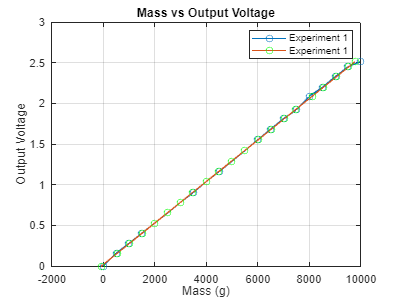

V_out = [0,0.1596, 0.2797, 0.4046, 0.5295, 0.6536, 0.7842, 0.9051, 1.04, 1.163, 1.29, 1.42, 1.554, 1.684, 1.813, 1.921, 2.089, 2.198, 2.328, 2.449, 2.518];
g_measure = [619, 1119, 1618,2118, 2616, 3127,3620,4159,4652,5161,5680,6215,66734,7253,7682,8356,8791,9310,9797,10071];
G_into = [0,500,1000,1499.8,1999.7,2500.6,3000.7,3500.2,4000,4500,5000.3,5500.3,6001.3,6500.3,7000.3,7498.7,8002.3,8504.3,9000.3,9495.3,9995.3];

fit_linear = polyfit(V_out,G_into,1);
masss_fit = polyval(fit_linear, V_out);
figure;
plot(G_into, V_out, '-o', 'DisplayName', 'Experiment 1');
hold on;
plot(masss_fit, V_out, '-o','MarkerEdgeColor', 'g', 'DisplayName', 'Experiment 1');

xlabel('Mass (g)');
ylabel('Output Voltage');
title('Mass vs Output Voltage');
legend;
grid on;
hold off;

fprintf('Linear Fit Equation: mass = (Vrms - %.2f) / %.2f\n', fit_linear(2), fit_linear(1));

Linear Fit Equation: mass = (Vrms - -74.72) / 3920.37
